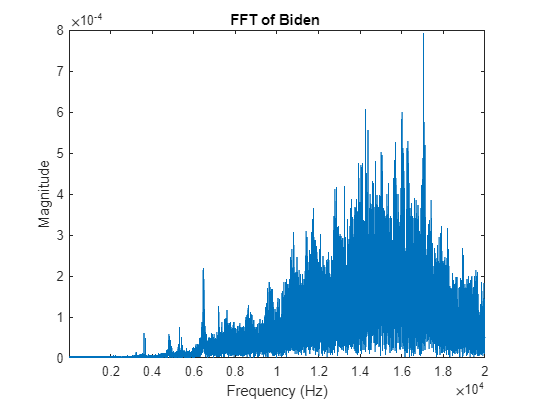

[audioData, Fs] = audioread('biden-original.wav'); 
audioLength = size(audioData, 1);
oneTenthLength = floor(audioLength / 10);
channel1Data = audioData(1:oneTenthLength, 1); 
plot(channel1Data);
xlabel('Sample Number');
ylabel('Amplitude');
title('REAL WAV File of Biden');

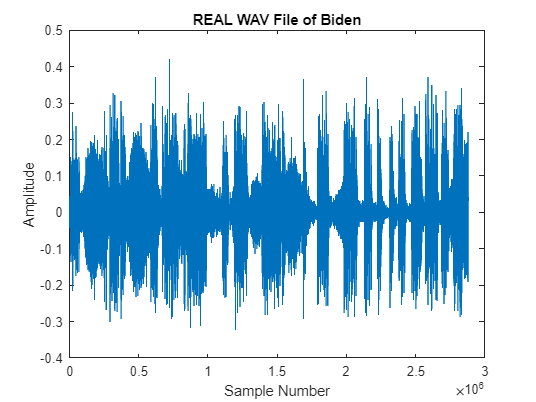


fftChannel1 = fft(channel1Data);

fftChannel1 = fftChannel1(1:length(channel1Data)/2+1);  

fftChannel1 = fftChannel1 / length(channel1Data); 

plot(abs(fftChannel1));
xlabel('Frequency (Hz)');
xlim([20,20000]);
ylabel('Magnitude');
title('FFT of Biden ');

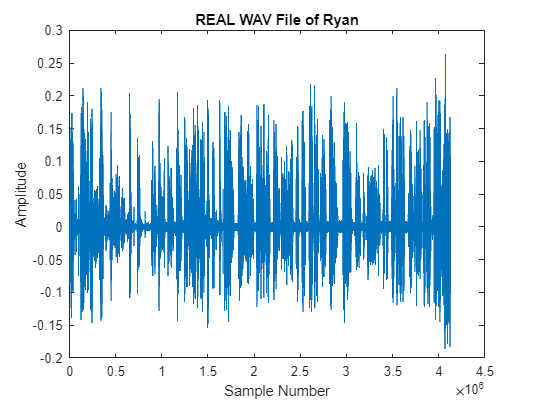

[audioData, Fs] = audioread('ryan-original.wav');  
channel1Data = audioData(:, 1); 
plot(channel1Data);
xlabel('Sample Number');
ylabel('Amplitude');
title('REAL WAV File of Ryan');


fftChannel1 = fft(channel1Data);

fftChannel1 = fftChannel1(1:length(channel1Data)/2+1); 

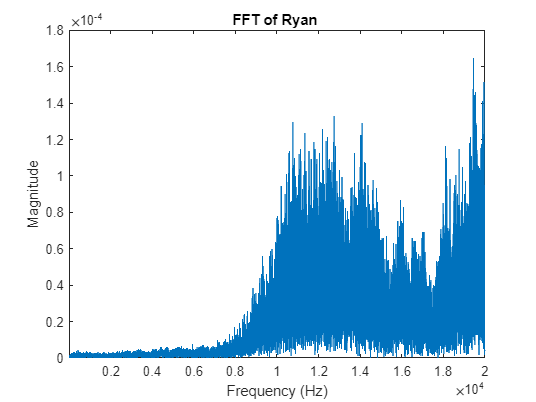


fftChannel1 = fftChannel1 / length(channel1Data);  

plot(abs(fftChannel1));
xlabel('Frequency (Hz)');
xlim([20,20000]);
ylabel('Magnitude');
title('FFT of Ryan ');

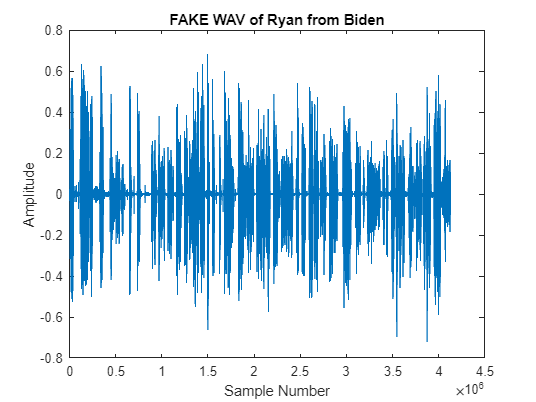

[audioData, Fs] = audioread('ryan-to-biden.wav');  
channel1Data = audioData(:, 1);  
plot(channel1Data);
xlabel('Sample Number');
ylabel('Amplitude');
title('FAKE WAV of Ryan from Biden');


fftChannel1 = fft(channel1Data);

fftChannel1 = fftChannel1(1:length(channel1Data)/2+1);  

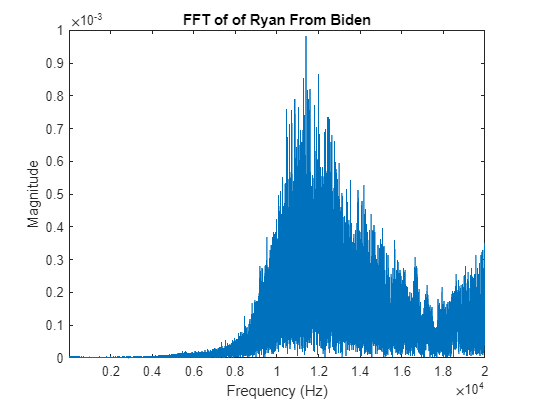


fftChannel1 = fftChannel1 / length(channel1Data);  

plot(abs(fftChannel1));
xlabel('Frequency (Hz)');
xlim([20,20000]);
ylabel('Magnitude');
title('FFT of of Ryan From Biden');

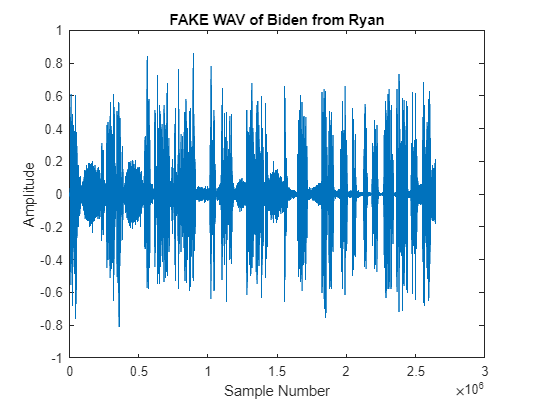


[audioData, Fs] = audioread('biden-to-ryan.wav');  
audioLength = size(audioData, 1);
oneTenthLength = floor(audioLength / 10);
channel1Data = audioData(1:oneTenthLength, 1);  
plot(channel1Data);
xlabel('Sample Number');
ylabel('Amplitude');
title('FAKE WAV of Biden from Ryan');

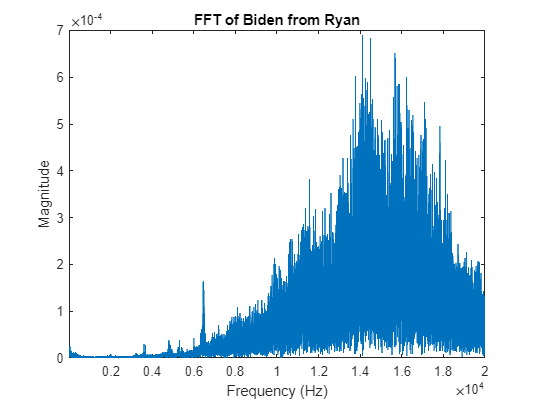


fftChannel1 = fft(channel1Data);

fftChannel1 = fftChannel1(1:length(channel1Data)/2+1);  

fftChannel1 = fftChannel1 / length(channel1Data);  

plot(abs(fftChannel1));
xlabel('Frequency (Hz)');
xlim([20,20000]);
ylabel('Magnitude');
title('FFT of Biden from Ryan');